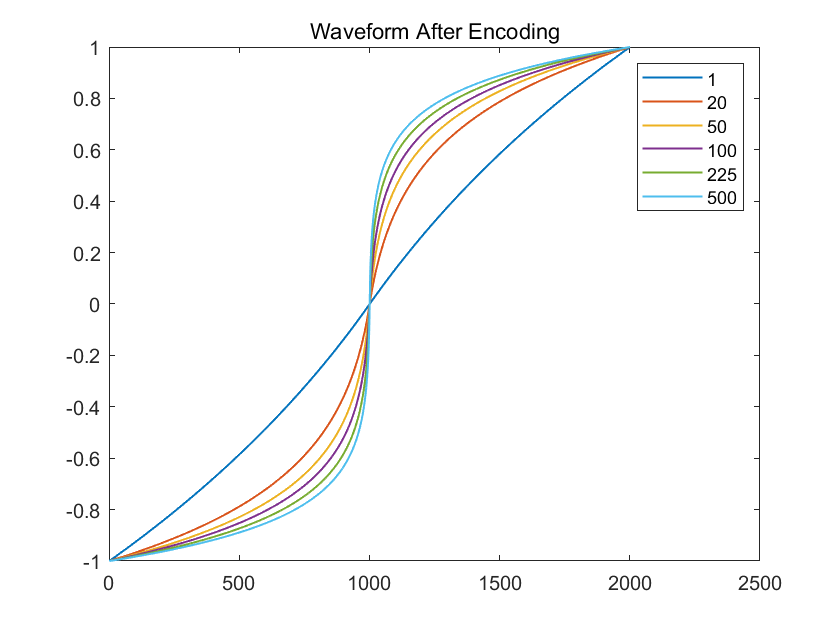

x = (-1:0.001:1);
figure
plot(mulaw(x,1), 'LineWidth',1), hold on;
plot(mulaw(x,20), 'LineWidth',1), hold on;
plot(mulaw(x,50), 'LineWidth',1), hold on;
plot(mulaw(x,100), 'LineWidth',1), hold on;
plot(mulaw(x,225), 'LineWidth',1), hold on;
plot(mulaw(x,500), 'LineWidth',1), hold off;
title('Waveform After Encoding')
legend('1', '20', '50', '100', '225', '500');
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P1_a.png", 'png')

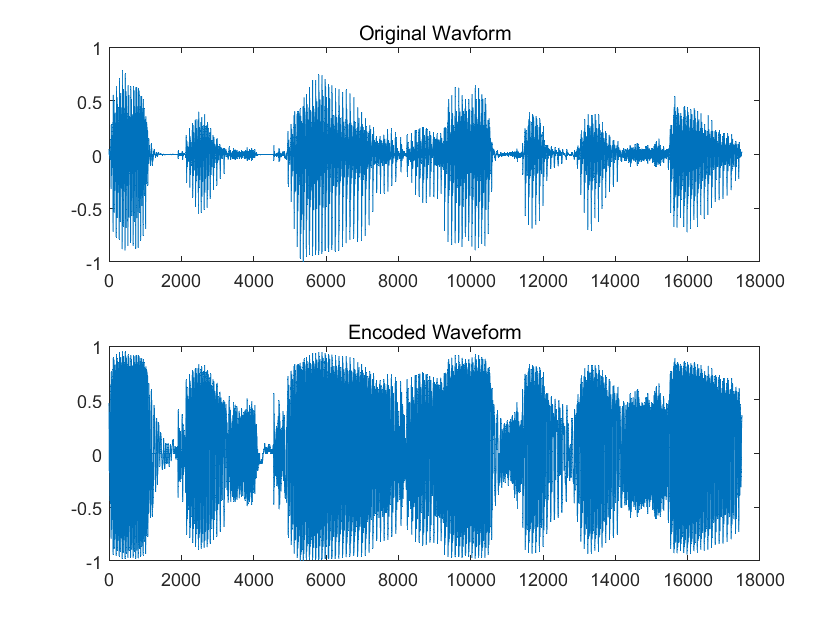

[y, fs] = audioread('s5.wav');
y = y(1300:18800);
figure
subplot(211)
plot(y), title('Original Wavform')
subplot(212)
plot(mulaw(y, 225)), title('Encoded Waveform')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P1_b_1.png", 'png')

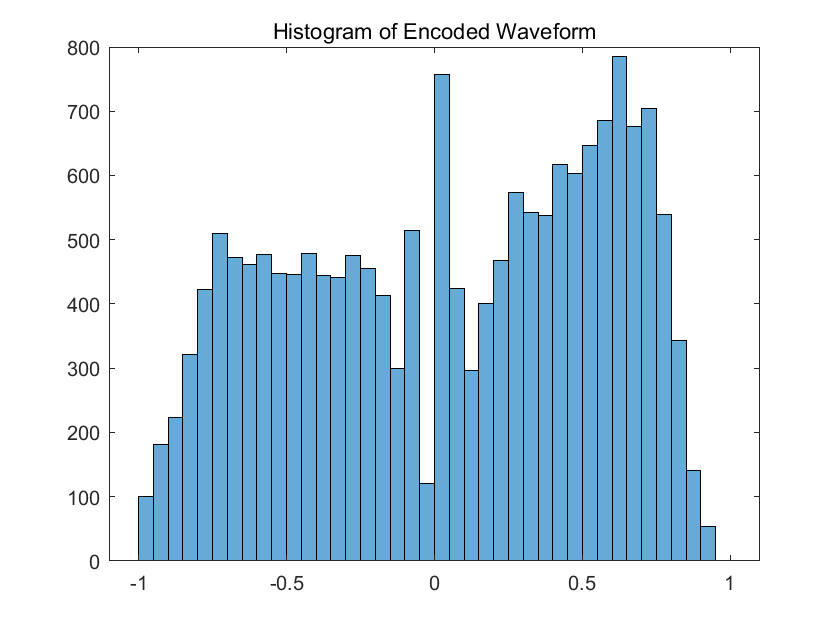

% 直方图
figure
histogram(mulaw(y, 225))
title('Histogram of Encoded Waveform')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P1_b_2.png", 'png')


% Problem C
v = my_mulawinv(mulaw(y, 225), 225);
mean(v-y)

ans = 4.6171e-19

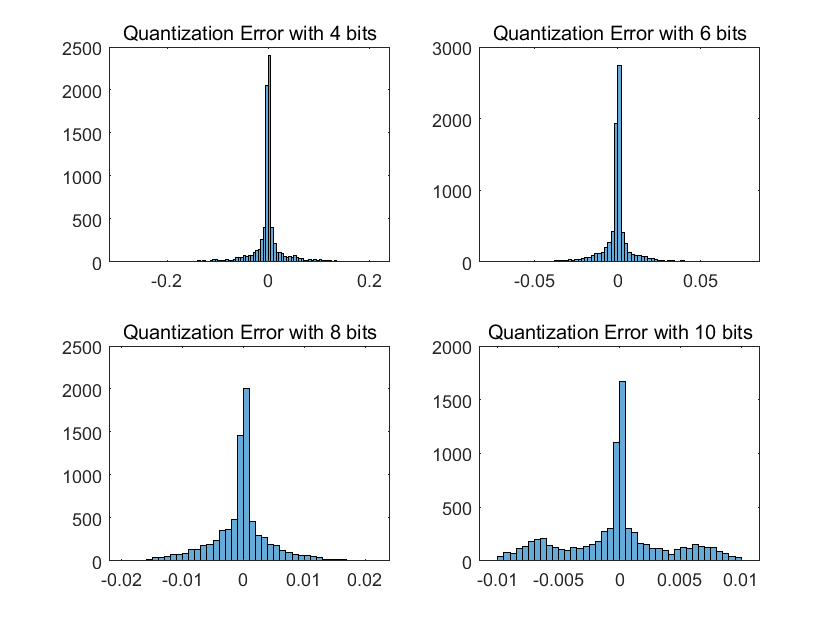

[x, fs] = audioread('s5.wav');
% Problem D
yh_4 = fxquant(mulaw(x, 225), 4, 'round', 'sat');
yh_8 = fxquant(mulaw(x, 225), 8, 'round', 'sat');
yh_10 = fxquant(mulaw(x, 225), 10, 'round', 'sat');
yh_6 = fxquant(mulaw(x, 225), 6, 'round', 'sat');
e_4 = mulawinv(yh_4, 255) - x;
e_6 = mulawinv(yh_6, 255) - x;
e_8 = mulawinv(yh_8, 255) - x;
e_10 = mulawinv(yh_10, 255) - x;
e_4 = e_4(1:8000);
e_6 = e_6(1:8000);
e_8 = e_8(1:8000);
e_10 = e_10(1:8000);
% histogram
figure
subplot(221), histogram(e_4), title('Quantization Error with 4 bits')
subplot(222), histogram(e_6), title('Quantization Error with 6 bits')
subplot(223), histogram(e_8), title('Quantization Error with 8 bits')
subplot(224), histogram(e_10), title('Quantization Error with 10 bits')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P1_d_1.png", 'png')

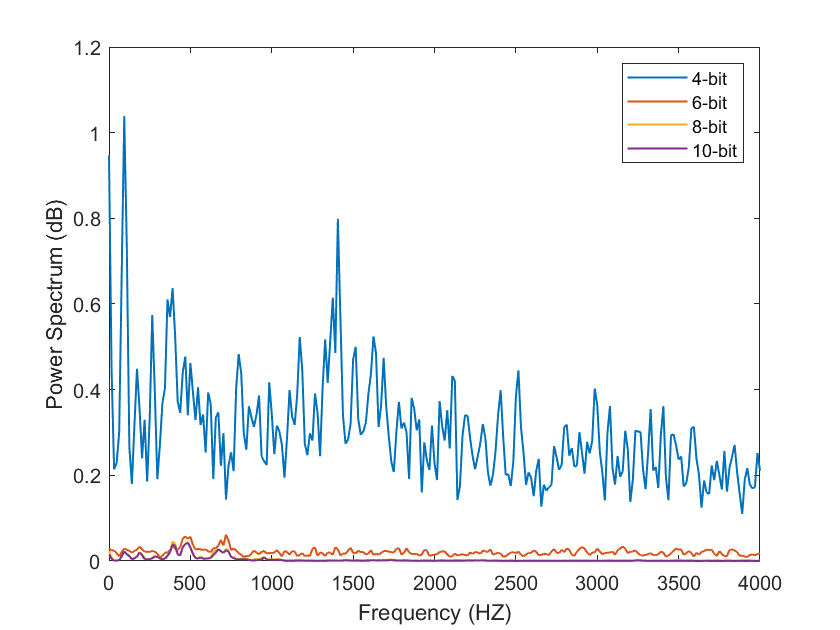


% Power Spectrum
win_len = 512;
[p_4, f4] = pspect(e_4, fs, win_len, win_len);
[p_6, f6] = pspect(e_6, fs, win_len, win_len);
[p_8, f8] = pspect(e_8, fs, win_len, win_len);
[p_10, f10] = pspect(e_10, fs, win_len, win_len);
figure
plot(f4, p_4, 'LineWidth',1), hold on;
plot(f6, p_6, 'LineWidth',1), hold on;
plot(f8, p_8, 'LineWidth',1), hold on;
plot(f10, p_10, 'LineWidth',1), hold off;
xlabel('Frequency (HZ)');
ylabel('Power Spectrum (dB)');
legend('4-bit', '6-bit', '8-bit', '10-bit');
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P1_d_2.png", 'png')

function x = my_mulawinv(y, mu)
    % 计算幅度部分
    abs_x = ( (1 + mu) .^ abs(y) - 1 ) / mu;
    % 恢复符号
    x = abs_x .* sign(y);
end